# Parcial 2 Control y Sistemas

**Nombre y apellido alumno:**

obsv

## Objetivos

Proponer una solución a la siguiente problemática utilizando conceptos de la materia y el criterio de ingeniería construido en las clases. 

Guardar este template en su directorio de trabajo con el siguiente nombre (colocando su nombre). Lo mismo para el enunciado de simulink/simscape.

`parcial2_livescript_NOMBRE_APELLIDO.mlx   (live script)`

`parcial2_planta_NOMBRE_APELLIDO.slx   (simulink/simscape)`

Una vez finalizado el examen enviar los 5 archivos: 1 live script + 4 archivos de simulink que se realizarán a medida que avance en el examen a las siguiente dirección de correo:

`carloshernangarrido@gmail.com`

    `CC: `

    `mauricio.caceres@ingenieria.uncuyo.edu.ar`

## Sección 1: Diseño y validación de planta

Construya un modelo en simulink usando simscape (mecánica traslacional) de la suspensión de un cuarto de vehículo (un colectivo).Los parámetros se dan abajo.Las perturbaciones del terreno aparecen a los 50 segundos y se modelan como un ruido de `1 m/s^2 RMS` (el bloque Band-Limited White Noise ya está configurado). SI EL MODELO ES CORRECTO, generan compresiones de la suspensión de 3 a 4 cm pico.

Guarde la solución en un archivo con nombre:  "`parcial2_planta_NOMBRE_APELLIDO.slx"`

%% Parameters (golden car)
clc
clear
close all
%kp = 1.2052e+05;
%ki = 6.4939e+05;
%kd = 5.5916e+03;

% kp = 3.0030e+05
% ki = 1.0458e+06
% kd = 1.8325e+04

m_s = 3000;  % Sprung mass (masa del chasis por rueda) (kg)
k_s = 63.3*m_s;  % Spring stiffness (rigidez del resorte) (N/m)
c_s = 6*m_s;  % Damping coefficient (coeficiente de amortiguamiento del amortiguador) (Ns/m)
k_t = 653*m_s;  % Tire stiffness (rigidez del neumático) (N/m)
c_t = 0;  % Tire damping (Ns/m)
m_u = 0.15*m_s;  % (masa de la rueda) Unsprung mass (kg)

## Sección 2: Diseño de control PID

- Haga una copia del modelo de simulink/simscape. Coloque como nombre

`parcial2_PID_NOMBRE_APELLIDO.slx `

Considerando un sensor ideal de distancia para medir la compresión de la suspensión: Implemente un PID para que el colectivo descienda y permita el ingreso de pasajeros. 

Este controlador, cuando el chofer da un escalón a la referencia de -15 cm a los 10 s, debe hacer que la suspensión se comprima 15 cm,  sin error en estado estacionario, sin sobre-impulso y con un tiempo de establecimiento de menos de 1.0 s.

Por otra parte, cuando sube el pasajero, modelado como perturbación tipo escalón de 700 N a los 20 s, el controlador debe rechazar la perturbación con un tiempo de establecimiento de menos de 1.0 s.

Para esto puede usar el comando 

%pidTuner(H, 'PID');

y obtener las ganancias por tanteo observando la tabla mostrada al pulsar el botón` Show Parameters.`Completar  los valores faltantes en las matrices a continuación para poder ejecutar el script

%% Diseño del PID
% x = [pos_u
%      pos_s
%      vel_u
%      vel_s]

M = [m_u 0
     0   m_s];
K = [k_s+k_t -k_s
     -k_s     k_s]

K =      2148900     -189900
     -189900      189900


C = [c_s+c_t -c_s
     -c_s     c_s]

C =        18000      -18000
      -18000       18000


A_ss = [ 0 0 1 0 
         0 0 0 1
        -M\K -M\C] 

A_ss = 	1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -4.7753    0.4220   -0.0400    0.0400
    0.0633   -0.0633    0.0060   -0.0060



B_ss = [ 0
         0
         (M^-1) * [ -1
                     1 ]]

B_ss =          0
         0
   -0.0022
    0.0003


Bd_ss = [0
         0
         0 
         -1/m_s]

Bd_ss = 	1.0e+-3 *

         0
         0
         0
   -0.3333


B = [B_ss Bd_ss]

B =          0         0
         0         0
   -0.0022         0
    0.0003   -0.0003


C_ss = [-1 1 0 0]

C_ss =     -1     1     0     0


D_ss = [ 0 ]

D_ss = 0

     
H  = tf(ss(A_ss, B_ss, C_ss, D_ss))

H =
 
         0.002556 s^2 - 4.54e-18 s + 1.451
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.



Hd = tf(ss(A_ss, Bd_ss, C_ss, D_ss))

Hd =
 
       -0.0003333 s^2 - 5.921e-19 s - 1.451
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.



%stepinfo(H)

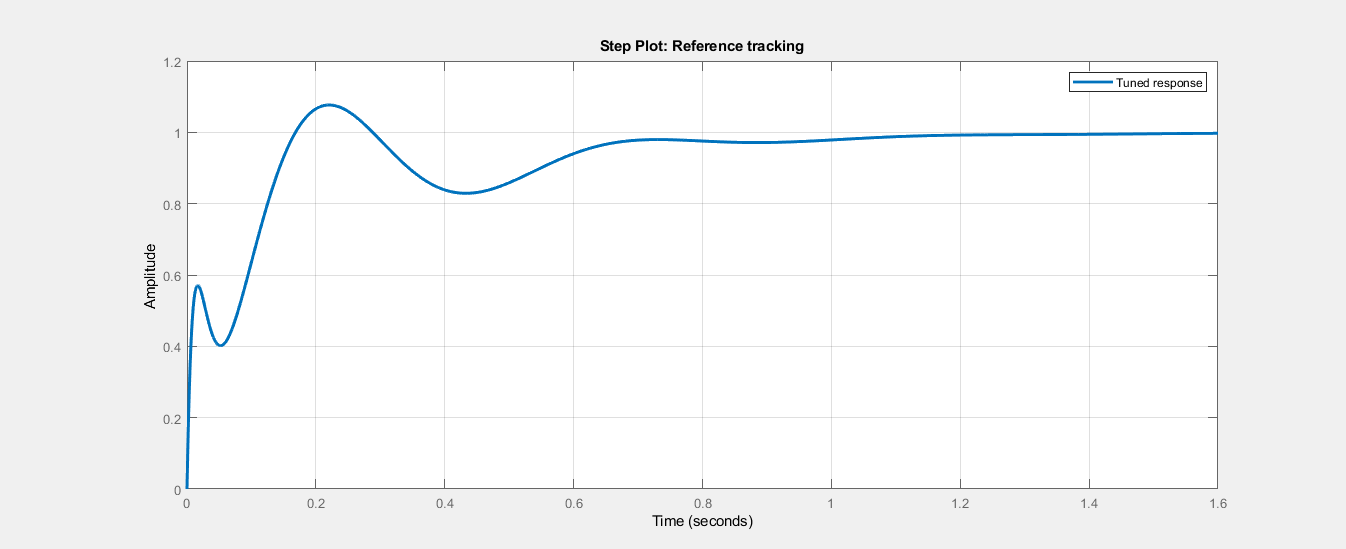

pidTuner(H, 'PID');

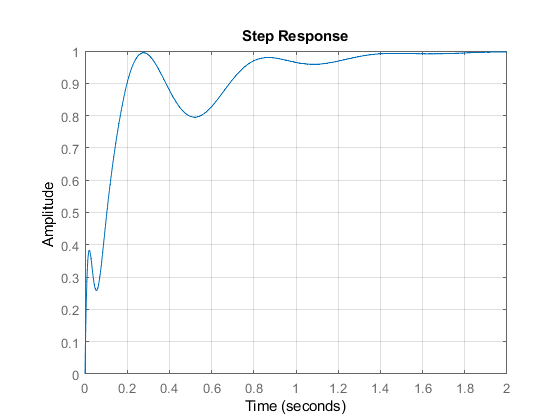

kp = controler.Kp*2.2;
ki = controler.Ki*1.48;
kd = controler.Kd*2.78;
Gc   =  tf([kd kp ki], [1 0]);
Gcl  =  Gc*H/(1 + Gc*H);
Gcld =  Hd/(1 + Gc*H);
step(Gcl); grid on;xlim([0,2])

stepinfo(Gcl)

ans = struct with fields:
        RiseTime: 0.1969
    SettlingTime: 1.2766
     SettlingMin: 0.7951
     SettlingMax: 0.9970
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9970
        PeakTime: 1.9344


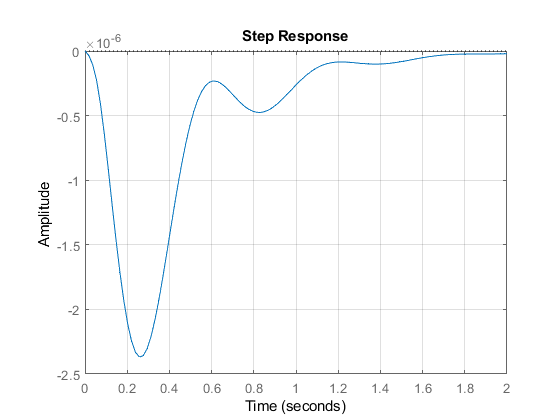

step(Gcld); grid on;xlim([0,2])

stepinfo(Gcld)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.6172
     SettlingMin: -2.3686e-06
     SettlingMax: -1.1813e-09
       Overshoot: Inf
      Undershoot: Inf
            Peak: 2.3686e-06
        PeakTime: 0.2576


kp

kp = 3.0030e+05

ki

ki = 1.0458e+06

kd

kd = 1.8325e+04

## Sección 3: Limitación de la acción de control del sistema

- Haga una copia del modelo de simulink/simscape. Coloque como nombre

`parcial2_PID_avanzado_NOMBRE_APELLIDO.slx`

Modifique el controlador de manera que la acción de control nunca supere los 20000 N en valor absoluto. Tendrá que agregar algún/algunos bloque/bloques. Se permite degradación del desempeño ante el escalón en la referencia, pero ante el escalón de la perturbación debe mantener la dinámica

## Sección 4: Control LQR

- Haga una copia del modelo de simulink/simscape de la sección 1

- Elimine el bloque PID, pero mantenga el modelo de la planta en simscape. Coloque el nombre

`parcial2_LQR_NOMBRE_APELLIDO.slx `

Agregue un controlador LQR ($K$), con seguimiento de referencia por feedforward ($k_r$), y acción integral ($k_i$). LAs matrices de ganancias $K$, $k_i$ y $k_r$ deben estar explícitas en el diagrama en bloques. 

No es necesario diseñar los valores óptimos para $K$, $k_i$ y $k_r$ (puede asignar valores 1 a todos los elementos como prueba), pero el modelo debe poder ejecutarse. Es decir, las dimensiones de las matrices deben ser consistentes para que simulink no de error.

comp_typ = 0.15;
comp_dot_typ = 0.15;
Aaug = [A_ss  zeros(4, 1)
        C_ss      0     ];
Baug = [B_ss; 0];
ytyp   = comp_typ*  0.47; 
y2typ  = comp_dot_typ*0.54; 
errtyp = 0.58; 
utyp   = 20e4*   5.55;

Cpaux  = [C_ss; 0 -1 0 1];
Qyaug   = [1/(ytyp^2)      0          0
            0        1/(y2typ^2)      0
            0             0       1/(errtyp^2)];
Qu = 1/utyp^2;
Cpauxaug = [Cpaux   zeros(2, 1)
            0     0    0   0   1];
Qxaug    = Cpauxaug'*Qyaug*Cpauxaug

Qxaug =   201.1971 -201.1971         0         0         0
 -201.1971  353.6129         0 -152.4158         0
         0         0         0         0         0
         0 -152.4158         0  152.4158         0
         0         0         0         0    2.9727


[Kaug, S] = lqr(Aaug, Baug, Qxaug, Qu); % por alguna razón no se puede
K_LQR         = Kaug(1:end-1)

K_LQR = 	1.0e+07 *

   -1.5600    2.1906    0.0016    1.3699


ki_LQR = Kaug(end)

ki_LQR = 1.9138e+06

kr = 1/(C_ss*(-(A_ss-B_ss*K_LQR)\B_ss))

kr = 2.2096e+07